## Transonic Aerodynamics - HW1

Shalom Carmona

Nicolas Tran

Steady 1D Euler equations

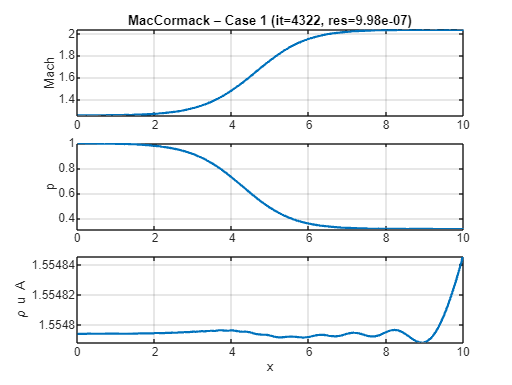

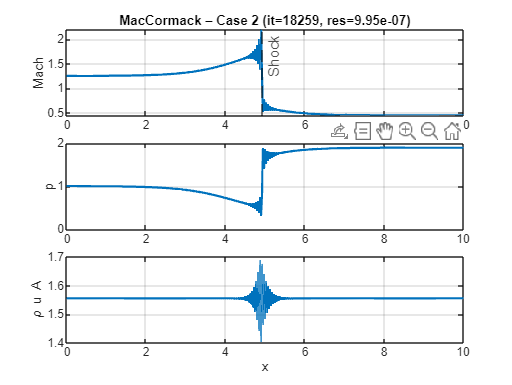

clear; clc; close all;

%params
gamma = 1.4;
cfl   = 0.5; % pseudo-time CFL
N     = 401; % grid points
L     = 10;
Min   = 1.25; % inlet mach
rho_in = 1; T_in = 1; p_in = rho_in*T_in;
p_back_factor = 1.9; % for case 2
maxIter = 2e4; tol = 1e-6;

% geom
x  = linspace(0,L,N); dx = x(2)-x(1);
A  = 1.398 + 0.347*tanh(0.8*x - 4);
dA = 0.347*0.8*(1 - tanh(0.8*x - 4).^2);

% inlet prim state
a_in = sqrt(gamma*p_in/rho_in);
u_in = Min*a_in;
e_in = p_in/(gamma-1) + 0.5*rho_in*u_in^2;

% two cases
for case_id = [1 2]
    [Q, it, res] = macCormack_nozzle(gamma, cfl, x, A, dA, ...
        rho_in, u_in, e_in, p_in, p_back_factor, maxIter, tol, case_id);

    % post-process
    rho = Q(1,:)./A; u = Q(2,:)./(rho.*A); e = Q(3,:)./A;
    p = (gamma-1)*(e - 0.5*rho.*u.^2);
    M = u./sqrt(gamma*p./rho);
    mdot = rho.*u.*A;

    % shock estimate
    xshock = NaN;
    if case_id==2
        k = find(M(1:end-1)>1 & M(2:end)<1,1);
        if ~isempty(k)
            xshock = x(k) + (1-M(k))*(x(k+1)-x(k))/(M(k+1)-M(k));
        end
    end

    %plots
    figure('Name',sprintf('Case %d',case_id));
    tiledlayout(3,1,"TileSpacing","compact");
    nexttile; plot(x,M,'LineWidth',1.5); grid on; ylabel('Mach');
    title(sprintf('MacCormack – Case %d (it=%d, res=%.2e)',case_id,it,res));
    if case_id==2 && ~isnan(xshock), xline(xshock,'k--','Shock'); end
    nexttile; plot(x,p,'LineWidth',1.5); grid on; ylabel('p');
    nexttile; plot(x,mdot,'LineWidth',1.5); grid on; ylabel('\rho u A'); xlabel('x');
end


%local functions
function [Q, it, res] = macCormack_nozzle(gamma, cfl, x, A, dAdx, ...
    rho_in, u_in, e_in, p_in, p_back_factor, maxIter, tol, case_id)

N = numel(x); dx = x(2)-x(1);
Q = zeros(3,N);
Q(1,:) = rho_in*A; Q(2,:) = rho_in*u_in*A; Q(3,:) = e_in*A;

useAV = (case_id==2); k2 = 0.06; epsTiny = 1e-12;

res = inf; it = 0;
while it<maxIter && res>tol
    it = it + 1;

    % primitives
    rho = Q(1,:)./A; u = Q(2,:)./(rho.*A); e = Q(3,:)./A;
    p = (gamma-1)*(e - 0.5*rho.*u.^2);
    a = sqrt(gamma*p./rho);
    dt = min( cfl*dx ./ (abs(u)+a) );

    % flux & source
    F = [rho.*u.*A; (rho.*u.^2+p).*A; u.*(e+p).*A];
    S = [zeros(1,N); p.*dAdx; zeros(1,N)];

    % av jameson 2nd-diff
    D = zeros(3,N);
    if useAV
        num = abs([p(2)-2*p(1)+p(2), p(3:end)-2*p(2:end-1)+p(1:end-2), p(end-1)-2*p(end)+p(end-1)]);
        den = p(3:end)+2*p(2:end-1)+p(1:end-2)+epsTiny;
        eps2 = zeros(1,N); eps2(2:end-1) = k2*(num(2:end-1)./den);
        for m=1:3
            D(m,2:end-1) = eps2(2:end-1).*(Q(m,3:end)-2*Q(m,2:end-1)+Q(m,1:end-2));
        end
    end

    % predictor
    Qp = Q;
    for i=1:N-1
        AVp = (D(:,i+1)-D(:,i))/dx;
        Qp(:,i) = Q(:,i) - dt/dx*(F(:,i+1)-F(:,i)) + dt*S(:,i) - dt*AVp;
    end

    % predicted flux/source
    rhop = Qp(1,:)./A; up = Qp(2,:)./(rhop.*A); ep = Qp(3,:)./A;
    pp = (gamma-1)*(ep - 0.5*rhop.*up.^2);
    Fp = [rhop.*up.*A; (rhop.*up.^2+pp).*A; up.*(ep+pp).*A];
    Sp = [zeros(1,N); pp.*dAdx; zeros(1,N)];

    Dp = zeros(3,N);
    if useAV
        num = abs([pp(2)-2*pp(1)+pp(2), pp(3:end)-2*pp(2:end-1)+pp(1:end-2), pp(end-1)-2*pp(end)+pp(end-1)]);
        den = pp(3:end)+2*pp(2:end-1)+pp(1:end-2)+epsTiny;
        eps2 = zeros(1,N); eps2(2:end-1) = k2*(num(2:end-1)./den);
        for m=1:3
            Dp(m,2:end-1) = eps2(2:end-1).*(Qp(m,3:end)-2*Qp(m,2:end-1)+Qp(m,1:end-2));
        end
    end

    % corrector
    Qn = Q;
    for i=2:N
        AVc = (Dp(:,i)-Dp(:,i-1))/dx;
        Qn(:,i) = 0.5*( Q(:,i)+Qp(:,i) - dt/dx*(Fp(:,i)-Fp(:,i-1)) + dt*Sp(:,i) - dt*AVc );
    end

    % bcs: supersonic inlet - full state
    Qn(:,1) = [rho_in*A(1); rho_in*u_in*A(1); e_in*A(1)];

    if case_id==1
        % supersonic outlet: extrapolate
        Qn(:,end) = Qn(:,end-1);
    else
        % subsonic outlet: p = 1.9 p_in
        p_back = p_back_factor * p_in;
        rhoN = Qn(1,end)/A(end);
        uN   = (Qn(2,end)/A(end))/rhoN;
        eN   = p_back/(gamma-1) + 0.5*rhoN*uN^2;
        Qn(:,end) = [rhoN*A(end); rhoN*uN*A(end); eN*A(end)];
    end

    res = max(abs(Qn(:)-Q(:)));
    Q   = Qn;
end
end
